# Part A

## Exercise 1

## 1

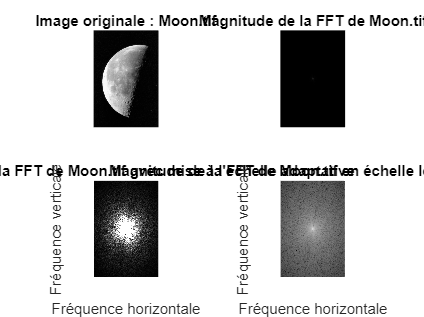


% Lecture des images "Moon.tif", "Fig_woman.tif", et "Fig_xray.tif"
moon = imread("Moon.tif");
woman = imread("Fig_woman.tif");
xray = imread("Fig_xray.tif");

% Application de la transformation de Fourier 2D (FFT) à chaque image
dft_moon = fft2(moon);
dft_woman = fft2(woman);
dft_xray = fft2(xray);

% Affichage des images dans une figure avec 9 sous-figures
figure,

% Affichage de l'image "Moon.tif" dans la première sous-figure avec un titre
subplot(2,2,1),
imshow(moon)
title('Image originale : Moon.tif')

% Calcul de la magnitude de la FFT de l'image "Moon.tif" et affichage dans la deuxième sous-figure avec un titre
F_moon = abs(fftshift(dft_moon));
subplot(2,2,2),
imshow(F_moon,[])
title('Magnitude de la FFT de Moon.tif')

% Détermination de la valeur minimale et maximale de la magnitude de la FFT de l'image "Moon.tif"
F_min_m = min(min(F_moon));
F_max_m = max(max(F_moon));

% Affichage de la magnitude de la FFT de l'image "Moon.tif" avec une mise à l'échelle adaptative dans la troisième sous-figure avec un titre
subplot(2,2,3),
imshow(F_moon,[1.5*F_min_m, F_max_m*1.e-3])
title('Magnitude de la FFT de Moon.tif avec mise à l''échelle adaptative')
xlabel('Fréquence horizontale')
ylabel('Fréquence verticale')

% Affichage de la magnitude de la FFT de l'image "Moon.tif" en échelle logarithmique dans la quatrième sous-figure avec un titre
subplot(2,2,4),
imshow(log(F_moon+1),[])
title('Magnitude de la FFT de Moon.tif en échelle logarithmique')
xlabel('Fréquence horizontale')
ylabel('Fréquence verticale')

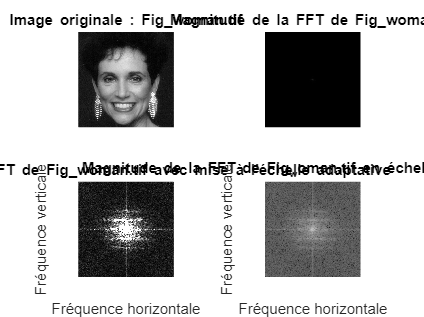


% Affichage de l'image "Fig_woman.tif" 
figure,
subplot(2,2,1),
imshow(woman)
title('Image originale : Fig\_woman.tif')

% Calcul de la magnitude de la FFT de l'image "Fig_woman.tif" 
F_woman = abs(fftshift(dft_woman));
subplot(2,2,2),
imshow(F_woman,[])
title('Magnitude de la FFT de Fig\_woman.tif')

% Détermination de la valeur minimale et maximale de la magnitude de la FFT de l'image "Fig_woman.tif"
F_min_w = min(min(F_woman));
F_max_w = max(max(F_woman));

% Affichage de la magnitude de la FFT de l'image "Fig_woman.tif" 
subplot(2,2,3),
imshow(F_woman,[1.5*F_min_w, F_max_w*1.e-3])
title('Magnitude de la FFT de Fig\_woman.tif avec mise à l''échelle adaptative')
xlabel('Fréquence horizontale')
ylabel('Fréquence verticale')

% Affichage dela magnitude de la FFT de l'image "Fig_woman.tif" en échelle logarithmique 
subplot(2,2,4),
imshow(log(F_woman+1),[])
title('Magnitude de la FFT de Fig_woman.tif en échelle logarithmique')
xlabel('Fréquence horizontale')
ylabel('Fréquence verticale')

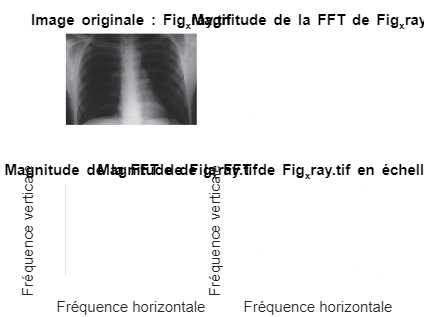


% Affichage de l'image "Fig_xray.tif" 
figure,
subplot(2,2,1),
imshow(xray)
title('Image originale : Fig_xray.tif')

% Calcul de la magnitude de la FFT de l'image "Fig_xray.tif" 
F_xray = abs(fftshift(dft_xray));
subplot(2,2,2),
imshow(F_xray,[])
title('Magnitude de la FFT de Fig_xray.tif')

% Détermination de la valeur minimale et maximale de la magnitude de la FFT de l'image "Fig_xray.tif"
F_min_x = min(min(F_xray));
F_max_x = max(max(F_xray));

% Affichage de la magnitude de la FFT de l'image "Fig_xray.tif" 
subplot(2,2,3),
imshow(F_xray,[ ])
title('Magnitude de la FFT de Fig_xray.tif')
xlabel('Fréquence horizontale')
ylabel('Fréquence verticale')

% Affichage de la magnitude de la FFT de l'image "Fig_xray.tif" en échelle logarithmique
subplot(2,2,4),
imshow(log(F_xray+1),[])
title('Magnitude de la FFT de Fig_xray.tif en échelle logarithmique')
xlabel('Fréquence horizontale')
ylabel('Fréquence verticale')

## 2

La magnitude de la DFT 2D d'une image représente la contribution de chaque fréquence spatiale à l'image. Les basses fréquences représentent des variations lentes de l'image, tandis que les hautes fréquences représentent des variations rapides de l'image.

Les propriétés de l'image telles que la netteté, la texture, la couleur et la luminosité peuvent être vues dans les tracés de magnitude de la DFT 2D. Par exemple, une image floue aura une réponse en fréquence plus faible aux hautes fréquences, tandis qu'une image nette aura une réponse en fréquence plus forte aux hautes fréquences.

De même, les régions uniformes de l'image auront une réponse en fréquence plus faible, tandis que les régions texturées auront une réponse en fréquence plus forte.

Ainsi, l'image de la Lune possède une région uniforme et symétrique au centre de l'image, ce qui est visible sur la magnitude de la FFT. De plus, l'image de la femme possède une symétrie verticale et horizontale. Elle est traduite par les 2 traits (vertical et horizontal). 

## Exercise 2

## 1

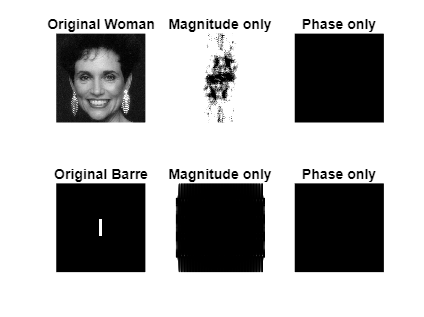


% Load the two grayscale images
woman = imread('Fig_woman.tif');
barre = imread('Fig_Barre500.tif');

% Compute the Fourier transforms of the images
woman_fft = fft2(double(woman));
barre_fft = fft2(double(barre));

% Extract the magnitude and phase information
woman_mag = abs(woman_fft);
woman_phase = angle(woman_fft);
barre_mag = abs(barre_fft);
barre_phase = angle(barre_fft);

% Reconstruct the images using only the magnitude or phase information
woman_mag_only = ifft2(woman_mag .* exp(1i*zeros(size(woman_phase))));
woman_phase_only = ifft2(zeros(size(woman_mag)) .* exp(1i*woman_phase));
barre_mag_only = ifft2(barre_mag .* exp(1i*zeros(size(barre_phase))));
barre_phase_only = ifft2(zeros(size(barre_mag)) .* exp(1i*barre_phase));

% Plot the original images and the reconstructed images
figure;
subplot(2,3,1); imshow(woman); title('Original Woman');
subplot(2,3,2); imshow(woman_mag_only, [0,25]); title('Magnitude only');
subplot(2,3,3); imshow(woman_phase_only, [75,175]); title('Phase only');
subplot(2,3,4); imshow(barre); title('Original Barre');
subplot(2,3,5); imshow(barre_mag_only, [0,25]); title('Magnitude only');
subplot(2,3,6); imshow(barre_phase_only, [75,175]); title('Phase only');

## 2

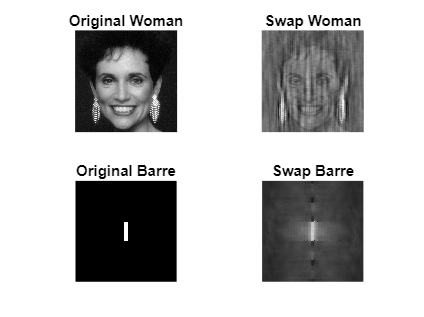

% Load the two grayscale images
woman = imread('Fig_woman.tif');
barre = imread('Fig_Barre500.tif');

% Compute the Fourier transforms of the images
woman_fft = fft2(double(woman));
barre_fft = fft2(double(barre));

% Swap the magnitudes and phases of the Fourier transforms
woman_swap = abs(barre_fft) .* exp(1i * angle(woman_fft));
barre_swap = abs(woman_fft) .* exp(1i * angle(barre_fft));

% Reconstruct the images using the swapped magnitudes and phases
woman_swap_image = ifft2(woman_swap);
barre_swap_image = ifft2(barre_swap);

% Plot the original images and the swapped images
figure;
subplot(2,2,1); imshow(woman); title('Original Woman');
subplot(2,2,2); imshow(real(woman_swap_image), []); title('Swap Woman');
subplot(2,2,3); imshow(barre); title('Original Barre');
subplot(2,2,4); imshow(real(barre_swap_image), []); title('Swap Barre');

## 3

Sur la base de cet exercice (ainsi que des résultats de l'exercice 1), on peut dire que à la fois l'amplitude et la phase sont importantes pour préserver les propriétés d'une image. Cependant, l'information de phase semble être plus critique que l'information d'amplitude.

Dans l'exercice 1, nous avons vu que lorsque nous avons reconstruit les images en utilisant uniquement l'amplitude ou uniquement la phase, les résultats étaient très différents de l'image d'origine. Cela suggère que à la fois l'amplitude et la phase sont importantes pour préserver les détails et les caractéristiques de l'image d'origine.

Dans l'exercice 2, lorsque nous avons échangé les amplitudes et les phases des transformées de Fourier et reconstruit les images, nous avons constaté que les images résultantes étaient encore reconnaissables mais avaient une apparence différente. Cela suggère que l'information de phase joue un rôle plus important dans la préservation des relations spatiales et de la structure de l'image, tandis que l'information d'amplitude contribue davantage à la luminosité et au contraste général de l'image.

La raison pour laquelle l'information de phase est plus importante que l'information d'amplitude est liée au fait que la transformation de Fourier décompose une image en ses composantes de fréquence. L'information de phase décrit les relations spatiales entre ces composantes de fréquence, ce qui détermine la structure et la forme des caractéristiques de l'image. D'autre part, l'information d'amplitude décrit simplement la force ou l'énergie de chaque composante de fréquence, qui contribue à la luminosité et au contraste général de l'image. Par conséquent, bien que à la fois l'amplitude et la phase soient importantes, l'information de phase est plus critique pour préserver la structure spatiale et les relations des caractéristiques de l'image.

## Exercise 3 – Linear Filtering of Images

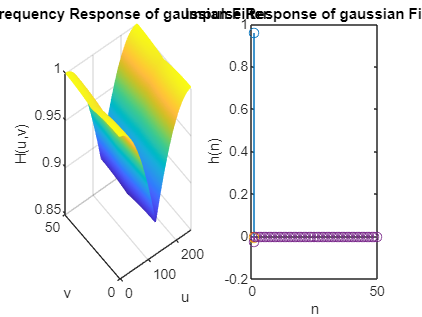

% Paramètres communs
M = 256;
N = 256;
D0 = 50;

% Condition I
ftype = 'gaussian';
[H, h] = lowpass_filter(ftype, D0, M, N);

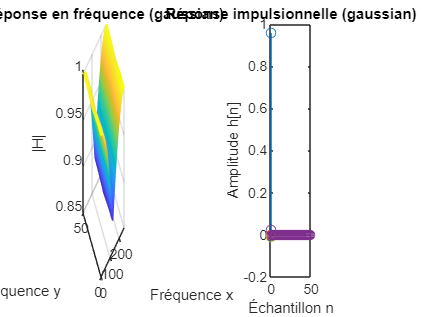

figure;
subplot(1, 2, 1);
mesh(abs(H));
title('Réponse en fréquence (gaussian)');
xlabel('Fréquence x');
ylabel('Fréquence y');
zlabel('|H|');
subplot(1, 2, 2);
stem(ifftshift(real(h)));
title('Réponse impulsionnelle (gaussian)');
xlabel('Échantillon n');
ylabel('Amplitude h[n]');

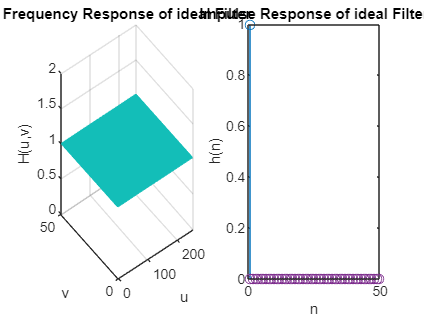


% Condition II
ftype = 'ideal';
[H, h] = lowpass_filter(ftype, D0, M, N);

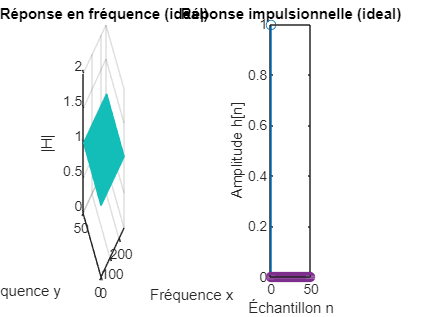

figure;
subplot(1, 2, 1);
mesh(abs(H));
title('Réponse en fréquence (ideal)');
xlabel('Fréquence x');
ylabel('Fréquence y');
zlabel('|H|');
subplot(1, 2, 2);
stem(ifftshift(real(h)));
title('Réponse impulsionnelle (ideal)');
xlabel('Échantillon n');
ylabel('Amplitude h[n]');

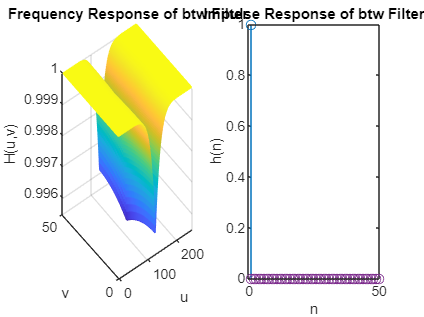


% Condition III
ftype = 'btw';
n = 4;
[H, h] = lowpass_filter(ftype, D0, M, N, n);

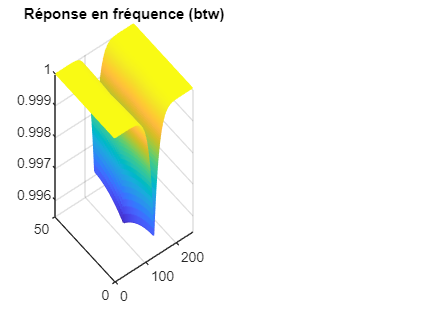

figure;
subplot(1, 2, 1);
mesh(abs(H));
title('Réponse en fréquence (btw)');

%xlabel('


function [H,h] = lpfilter(ftype, M, N, D0, n)
%LPFILTER Computes frequency response of lowpass filter
%  H = lpfilter('ftype', M, N, D0, n) computes the frequency response of
%  a lowpass filter H of type 'ftype', of size M-by-N, and cutoff D0.
%  For Butterworth filters, an additional parameter n can be specified.
%  The output H is the frequency response of the filter.
%  h is the impulse response of the filter.
%
%  Valid values for 'ftype' are:
%    'gaussian'
%    'ideal'
%    'btw' (Butterworth)
%

% Create a meshgrid of frequencies
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx) = u(idx)-M;
idy = find(v>N/2);
v(idy) = v(idy)-N;
[V, U] = meshgrid(v, u);
D = sqrt(U.^2 + V.^2);

% Compute the frequency response based on the filter type
switch ftype
    case 'ideal'
        H = double(D <=D0);
    case 'gaussian'
        H = exp(-(D.^2)./(2*(D0^2)));
    case 'btw'
        H = 1./(1 + (D./D0).^(2*n));
end

% Compute the impulse response using the inverse Fourier transform
h = real(ifft2(ifftshift(H)));

% Plot the frequency response and impulse response
figure;
subplot(1, 2, 1);
mesh(H);
title(['Frequency Response of ' ftype ' Filter']);
xlabel('u');
ylabel('v');
zlabel('H(u,v)');

subplot(1, 2, 2);
stem(h);
title(['Impulse Response of ' ftype ' Filter']);
xlabel('n');
ylabel('h(n)');
end

function [H, h] = lowpass_filter(type, M, N, D0, n)
% Design a lowpass filter of the given type and cutoff frequency D0
% type: 'gaussian', 'ideal', or 'btw'
% M, N: dimensions of the filter
% D0: cutoff frequency (normalized to range [0, M] or [0 N])
% n: filter order for Butterworth filters
% H: frequency response of the filter
% h: impulse response of the filter

% Design the filter
switch type
    case 'gaussian'
        H = lpfilter(type, M, N, D0);
    case 'ideal'
        H = lpfilter(type, M, N, D0);
    case 'btw'
        H = lpfilter(type, M, N, D0, n);
end

% Compute the impulse response
h = ifftshift(ifft2(H));
end